a = arduino('/dev/ttyUSB0', 'nano3');

%LED BLINK

writeDigitalPin(a, 'D13', 1);
pause(1);
writeDigitalPin(a, 'D13', 0);
pause(1);
writeDigitalPin(a, 'D13', 1);
pause(1);
writeDigitalPin(a, 'D13', 0);
pause(1);
writeDigitalPin(a, 'D13', 1);
pause(1);
writeDigitalPin(a, 'D13', 0);
pause(1);

%ANALOG READ
x = 1:100;

for iter = 1:100
    y(iter) = readVoltage(a, 'A0'); 
    y(iter) = y(iter) * (1023/5);
    scatter(x(iter),y(iter))
    hold on;
end

%scatter(x,y)
hold off;

%SENSOR VALUE CHECK

for data = 1:25
    distance(data) = input('INPUT DISTANCE IN cm: ');
    tempData = 0;
    
    for iter = 1:100   
        tempData(iter) = readVoltage(a,'A0')*(1023/5);
        %scatter(iter, tempData(iter))
        %hold on;
    end
    
    %hold off;
    value(data) = median(tempData)
end

%POLYFIT
parameters = polyfit(value,distance,3)

parameters =    -0.0000    0.0005   -0.2959   69.1564


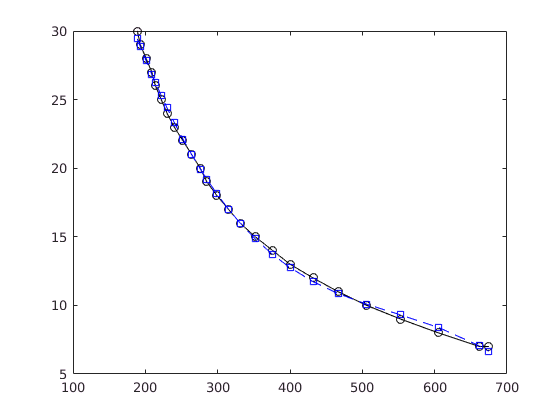

fittedDistance = polyval(parameters,value);
plot(value,distance,'-ko', value,fittedDistance,'--bs')

%RATIONAL FIT
rationalParameters = fit(value',distance','rat01')

rationalParameters =      General model Rat01:
     rationalParameters(x) = (p1) / (x + q1)
     Coefficients (with 95% confidence bounds):
       p1 =        4835  (4723, 4948)
       q1 =      -28.76  (-33.52, -24)

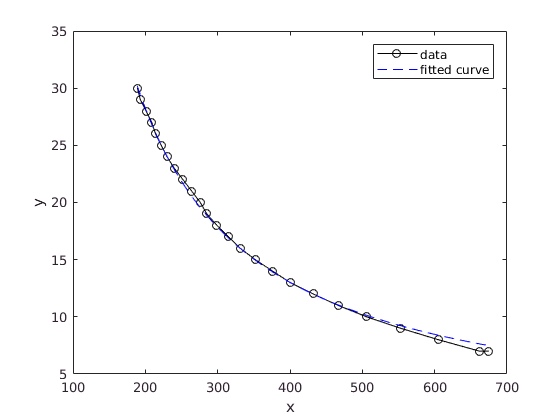

plot(rationalParameters,'--b',value,distance,'-ko')

%REVERSE CURVE FITTING
x = 200:700;
%y = 0.*(x.^3) + 0.0001.*(x.^2) - 0.1428.*x + 51.1766
y = 4835 ./ (x-28.76)

y =    28.2352   28.0713   27.9093   27.7491   27.5907   27.4342   27.2794   27.1263   26.9750   26.8253   26.6773   26.5309   26.3862   26.2429   26.1013   25.9611   25.8225   25.6853   25.5496   25.4153   25.2824   25.1509   25.0207   24.8919   24.7644   24.6382   24.5133   24.3896   24.2672   24.1460   24.0260   23.9072   23.7896   23.6731   23.5578   23.4436   23.3304   23.2184   23.1074   22.9975   22.8887   22.7808   22.6740   22.5681   22.4633   22.3594   22.2565   22.1545   22.0535   21.9533


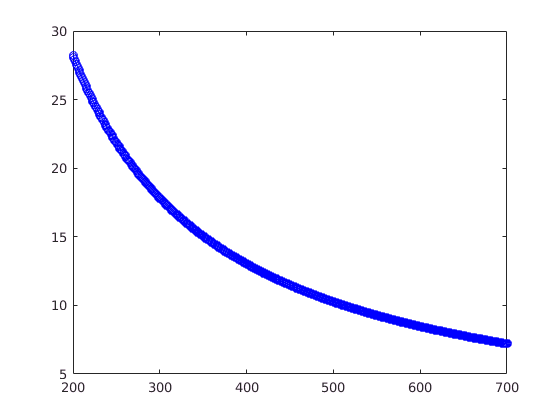

plot(x,y,'-bo');

%VERIFICATION
val = readVoltage(a,'A0') * (1023/5)

val = 249

y = 4835 / (val-28.76)

y = 20.9607

%y = 0.*(val.^3) + 0.0001.*(val.^2) - 0.1428.*val + 51.1766